## Name: Maria Eva Vazquez

## Date: 11/06/2026

## PID: 6296923

## Quiz 5 : Numerical Integration Ext

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

**Submission Instructions:** Quiz files should be titled Quiz_X_FirstNameLastName, Ex: Quiz_5_AsadMirza. To convert the MLX file into a PDF go to the Export icon under Live Editor and select "Export to PDF".

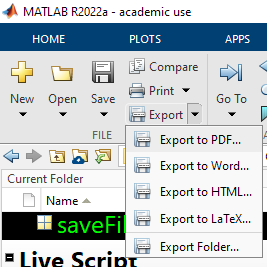

Any scratch paper used should have your name, date, and PID on it and be submitted to me when you finish your quiz.

Question 1 (50%) :

The popular FitzHugh-Nagumo model for a neuron is defined by the ODE pair:


$$\begin{array}{c}
\frac{dv}{dt}=v-\frac{v^3 }{3}-w+I\\
\frac{dw}{dt}=0\ldotp 08\left(v+0\ldotp 7-0\ldotp 8w\right)
\end{array}$$


where 

- $v$ is the voltage 

- $w$ is the linear recovery of the neuron

- $I$ is the input current

Initial values are:

- 
$$v\left(0\right)=0$$


- 
$$w\left(0\right)=1$$


a) (30%) Using MATLAB's ode45, solve the system over 120 ms with $I=0\ldotp 8$. Plot both $v\left(t\right)$ and $w\left(t\right)$ on the same graph. Your plot should include: labeled axes, title, and a legend.


$$s=\left\lbrack \begin{array}{c}
v\\
w
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack$$



$$s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{dv}{dt}=v-\frac{v^3 }{3}-w+I\\
\frac{dw}{dt}=0\ldotp 08\left(v+0\ldotp 7-0\ldotp 8w\right)
\end{array}\right\rbrack$$


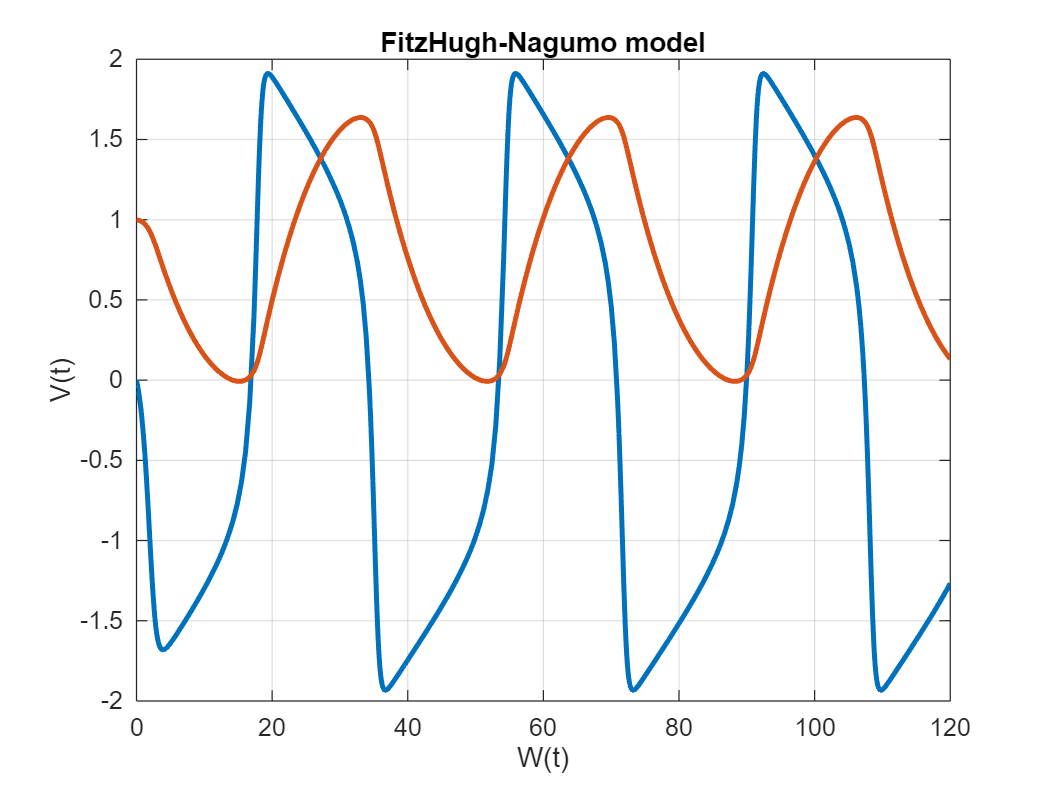

clear,clc,close all

% v = s(1)
% w = s(2)
% s=[ V    W  ]
% s=[s(1) s(2)]
% s'=[s(1)' s(2)']
% s'=[V- V^3/3 - W +I   0.08(V+0.7 -0.8 W))]
% s'=[s(1)- s(1)^3/3 - s(2) +I_unit   0.08(s(1)+0.7 -0.8 s(2)))] ????


% % Step 1
t_span= [0 120]; % for 120ms 
s0 = [ 0 ; 1 ]; % v0 = 0, w0 = 1
I_unit =0.8;

% % Step 2
f = @(t, s) [ s(1)- (s(1).^3)/3 - s(2) + I_unit  ; ... % first equation  % issue is here <<<
            0.08 * ( s(1) + 0.7 - 0.8*s(2) ) ]; % second equation

% % Step 3
[t, s] = ode45(f, t_span, s0);

% % Step 4: Plotting
figure;
plot(t, s, 'LineWidth', 2);
ylabel('W(t)');
xlabel('V(t)');
title('FitzHugh-Nagumo model');
grid on;

b) (20%) Neurons respond differently depending on the input current, investigate this effect with the following values for $I$:


$$I=\left\lbrack 0,\;0\ldotp 2,\;0\ldotp 4,\;0\ldotp 6,\;0\ldotp 8,\;1\ldotp 0\right\rbrack$$


Solve the model using ode45 for 120 ms and plot the voltage, $v\left(t\right)$, for all simulations on the same figure. Your plot should include: labeled axes, title, and a legend.

Then, briefly comment (2-3 sentences) on:

- How the voltage signal changes as the injected current $I$ increases.

- At approximately what value of $I$ the neuron begins to exhibit action potential spikes.


% % Step 1
t_span= [0 120]; % for 120ms 
s0 = [ 0 ; 1 ]; % v0 = 0, w0 = 1
I_units = [0 ; 0.2 ; 0.4 ; 0.6 ; 0.8 ; 1]; 

% % Step 2

for k = 1:length(I_units)
    omega=I_units(k);
    f = @(t, s) [ s(1)- (s(1).^3)/3 - s(2) + I_units; ... % first equation 
            0.08 * ( s(1) + 0.7 - 0.8*s(2) ) ]; % second equation

    % Solve the ODE for each gamma value
    [t, s] = ode45(f, t_span, s0);
    plot(t, y(:,1), 'DisplayName', ['\omega = ' num2str(omega)], 'LineWidth', 2); % Plot voltage
    ylabel('V(t)');
    xlabel('W(t)');
    grid on;
end

Error using odearguments (line 98)
@(T,S)[S(1)-(S(1).^3)/3-S(2)+I_UNITS;0.08*(S(1)+0.7-0.8*S(2))] returns a vector of length 7, but the length of initial conditions vector is 2. The vector returned by @(T,S)[S(1)-(S(1).^3)/3-S(2)+I_UNITS;0.08*(S(1)+0.7-0.8*S(2))] and the initial conditions vector must have the same number of elements.

Error in ode45 (line 104)
    odearguments(odeIsFuncHandle,odeTreatAs

Question 2 (50%): 

Consider the following equation when $\frac{\textrm{dq}\left(0\right)}{\textrm{dx}}=0$, $q\left(0\right)=4$, over a span of $x=\left\lbrack 0\;\;\;\;\;\;3\right\rbrack$


$$\frac{d^2 q}{{dx}^2 }+4q=110\cos \left(5x\right)-4\frac{dq}{dx}$$


a) (40%) Fill out the state system ($\left.s\right)$ and its derivative $\left(s^{\prime } \right)$ below, make sure your final answer for $s^{\prime }$ is defined using $s_1$ and $s_2$.


$$\begin{array}{l}
s=\left\lbrack \begin{array}{c}
s_1 \\
s_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
q\\
\frac{\mathrm{dq}}{\mathrm{dx}}
\end{array}\right\rbrack \\
s^{\prime } =\left\lbrack \begin{array}{c}
{s_1 }^{\prime } \\
{s_2 }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\mathrm{s2}\\
110\cos \left(5x\right)-4\frac{dq}{dx}-4q
\end{array}\right\rbrack \;
\end{array}$$


b) (10%) Find the [analytical solution](https://www.mathworks.com/help/symbolic/solve-a-single-differential-equation.html) using the Symbolic Toolbox for $q\left(x\right)$ and plot it with appropriate axis labels and a title. 

clear,clc,close all

t_span = [0 3]
s0 = [4 0]


f = @(x, s) [s(2) ; ...  % First equation
             110*cos(5*x)-4*s(2) - 4*q]; % Second equation

% % Analytical 
syms wa(xa); % symbolic rep for  q(x) where s2 = xa
eqn = diff(wa, xa, 2) == 110*cos(5*xa)-4*xa- 4*wa; % defines the differential equation
 Dwa = diff(wa, xa); % symbolic rep for the first derivative
 cond = [wa(0) == 4, Dwa(0) == 0]; % Initial conditions 
wSol(xa) = dsolve(eqn, cond); % computes the exact solution

% % Step 5: Plotting
figure;
xx = linspace(0, 5); % for a smoothness
plot(xx, wSol(xx), 'r', 'LineWidth', 2); % exact
hold on;
plot(x, s(:, 1), '--b', 'LineWidth', 2); % ode45
hold off;
ylabel('dq/dx(x)'); 
xlabel('q(x)'); 
title('Exact Solution vs ODE45');
legend('Exact','ODE45', 'Location', 'Best');
grid on; 
